# bacterial population

t = 0:7;
for i = 1:length(t)
    q(i) = quad('0.693*10*2.^t', 0, t(i));
end

fprintf('\n Hour Cells')


 Hour Cells

fprintf('5.0f 8.0f \n' , [floor(t);q])

5.0f 8.0f 


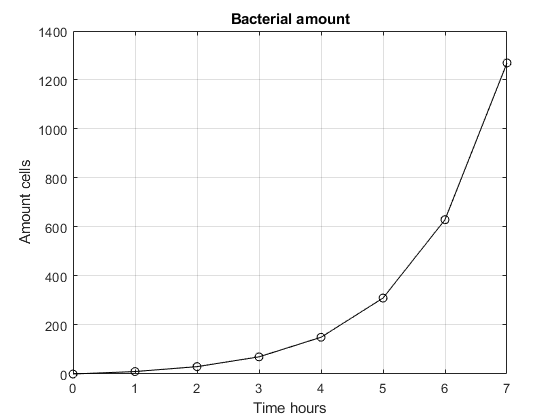


plot(t, q, '-ok')
title('Bacterial amount')
xlabel('Time hours'), ylabel('Amount cells')
grid

n = 1000;
a = 0;
b = 7;
dt = (b-a)/(n-1)

dt = 0.0070

t = a:dt:b

t =          0    0.0070    0.0140    0.0210    0.0280    0.0350    0.0420    0.0490    0.0561    0.0631    0.0701    0.0771    0.0841    0.0911    0.0981    0.1051    0.1121    0.1191    0.1261    0.1331    0.1401    0.1471    0.1542    0.1612    0.1682    0.1752    0.1822    0.1892    0.1962    0.2032    0.2102    0.2172    0.2242    0.2312    0.2382    0.2452    0.2523    0.2593    0.2663    0.2733    0.2803    0.2873    0.2943    0.3013    0.3083    0.3153    0.3223    0.3293    0.3363    0.3433


f = 0.6931*10*2.^t

f =     6.9310    6.9647    6.9987    7.0327    7.0670    7.1014    7.1360    7.1707    7.2056    7.2407    7.2759    7.3114    7.3470    7.3827    7.4187    7.4548    7.4911    7.5276    7.5642    7.6010    7.6380    7.6752    7.7126    7.7502    7.7879    7.8258    7.8639    7.9022    7.9407    7.9793    8.0182    8.0572    8.0964    8.1359    8.1755    8.2153    8.2553    8.2955    8.3359    8.3764    8.4172    8.4582    8.4994    8.5408    8.5823    8.6241    8.6661    8.7083    8.7507    8.7933


N7 = floor(dt*sum(f(1:end-1)))

N7 = 1266

fprintf('\n Bacterial amount after 7 hours')


 Bacterial amount after 7 hours

fprintf('Left Riemann N = %5.0f, Simpson N = %5.0f \n', N7, q(end))

Left Riemann N =  1266, Simpson N =  1270 
